**Ercihan Kara - 2375160**

## Data Acquisition and Data Generation

+ Sound data from a microphone:

    - Capture the voice by the help of a microphone   connected to the computer.

    - Analog-to-digital conversion sampling rate is adjustable on a user interface.

    - The total length of the generated data is also a user-specified parameter (guessing lifetime of mic input).

+ Sound data from a file:

    - Be able to process .wav or .mp3 sound files.

    - Retrieve the time-domain signal and the sampling frequency.

    - Use single channel.

+ If the input signal is a speech signal, the required process in order to record and save it is realized above.

+ System must be able to generate the samples of time-domain signals with some simple mathematical expressions.

+ The sampling frequency is a user-specified parameter. The total length of the generated data is also a user-specified parameter. It can be input in seconds or in number of samples.

clear all
clc
% USER INTERFACES
% initial interface to decide on whether the mic is used or a file is utilized:

type = "none";

user_int_decide = {'Input type (mic or file or custom):'};
title_inp = 'Choose input type';
dims = [1 40];
type_input = inputdlg(user_int_decide, title_inp, dims);

if type_input == "mic"
    type = "mic";
elseif type_input == "file"
    type = "file";
else
    type = "custom";
end

if type == "mic"
    % user interface to get the sampling rate

    user_int_mic = {'A-to-D sampling rate (Hz):','Length of the generated data (sec):','Number of letters in the word:'};
    title_inp = 'Type the sampling rate, length of voice, and number of letters';
    dims = [1 40];
    defalut_input = {'8000', '5', '0'};
    mic_inputs = inputdlg(user_int_mic, title_inp, dims, defalut_input);

elseif type == "file"
    % user interface to get the file address

    user_int_file = {'File address:'};
    title_inp = 'Type the address of the file';
    dims = [1 40];
    file_input = inputdlg(user_int_file, title_inp, dims);

else
    % user interface to get sampling rate and length for the custom signal

    user_int_custom = {'Signal frequency (Hz):','Sampling rate (Hz):','Length of the generated data (# of samples):'};
    title_inp = 'Type the signal frequency, sampling rate, and length of custom signal';
    dims = [1 8000 40];
    custom_inputs = inputdlg(user_int_custom, title_inp, dims);
end

% First consider the mic case:
% Create an audiorecorder object with the specified sampling rate using one channel:
if type == "mic"
    % audiorecorder creates and returns an audiorecorder object with specified properties

    samp_rate = str2double(mic_inputs(1)); % 8000 default
    bits = 8; % default
    channels = 1; % default
    ID = -1; % default
    
    % object created
    obj = audiorecorder(samp_rate, bits, channels, ID);
    
    % record the input voice
    % disp("SPEAK")
    duration = str2double(mic_inputs(2)); % users' desired time period
    recordblocking(obj, duration);
    % disp("FINITO")

    num_of_letter = str2double(mic_inputs(3)); % users' desired time period
    
    % save the voice data
    voice_mic = getaudiodata(obj, 'double');

    % play it to check
    play(obj);

% Then consider the file case:
elseif type == "file"
    % audioread reads data from the file, returns sampled data and sample
    % rate for the data

    [voice_file, samp_rate] = audioread(file_input);

% And consider the custom case:
else
    % create a sinusoidal signal for the "implementation" section as the
    % custom signal
    sig_freq = str2double(custom_inputs(1));
    length = str2double(custom_inputs(2));
    samp_rate = str2double(custom_inputs(3));
    t_custom = 0:length-1;

    % sinusoidal signal: 𝑥(𝑡)=𝐴cos(2𝜋𝑓𝑡+𝜃)
    magn = 1; % default assigned
    phase = 0; % default assigned
    signal = magn*cos(2*pi*sig_freq*t_custom + phase);
    plot(t_custom, abs(signal))
end

**Take the window signal type and create the STFT of the input signal:**

user_int_window = {'Window type (tukey, blackman, hamming, hanning, kaiser, gaussian, triangular, rectangular):','Window signal length:'};
title_inp = 'Choose window type and length';
dims = [1 80];
defalut_input = {'','200'};
win_inputs = inputdlg(user_int_window, title_inp, dims, defalut_input);

% create the STFT
win_len = str2double(win_inputs(2));
win_type = char(win_inputs(1)); 
shift = win_len/2;
num_fft = 2*win_len;

**1.a) Sound Signal**

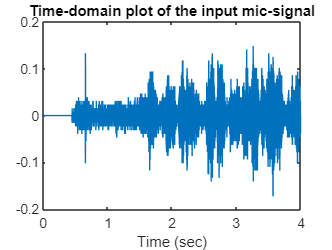

% Plot time domain signal and show the possible locations of letters
% Time-domain plot
t_axis = linspace(0, duration-1, duration*samp_rate);
plot(t_axis, voice_mic);
title('Time-domain plot of the input mic-signal');
xlabel("Time (sec)");

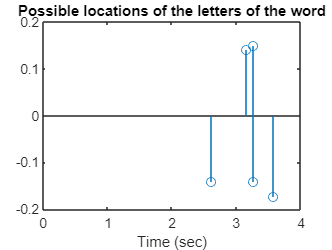


% Moments when the letters are used (possibly)
[max_values, moments] = maxk(voice_mic, num_of_letter, 'ComparisonMethod','abs');
stem(moments/10^4, max_values);
xlim([0 (duration-1)]);
title('Possible locations of the letters of the word');
xlabel("Time (sec)");

% Plot spectrogram of the signal
% Spectrogram plot
[time, freqs, STFT] = custom_stft(voice_mic, win_len, win_type, shift, num_fft, samp_rate);
mag_stft = abs(STFT);
freqs = freqs.';
win_sig = ones(1, win_len);
% in order to check
% [s, f, t] = spectrogram(voice_mic,win_sig,shift,num_fft,[],[],samp_rate, 'yaxis');
colormap default;

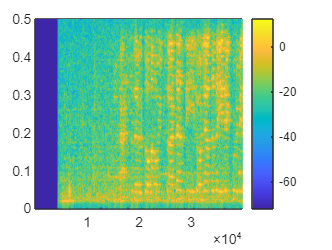

custom_spectrogram_plot(time, freqs, mag2db(mag_stft));

% Show the possible locations of letters on spectrogram plot
% Moments when the letters are used on spectrogram (possibly)
% time instances coming from original signal
abs_values = mag2db(mag_stft);
[max, indx] = maxk(abs_values, num_of_letter, 2); % computes the k largest values in each column